# **Uninfected**

## **GLOBULOS BLANCOS**

### **a) Anotaciones**

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Uninfected Patients\TF201_HT6\tiled'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.tiff'));

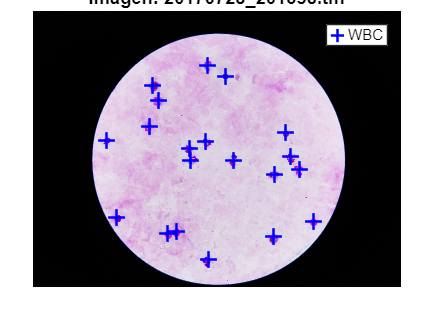

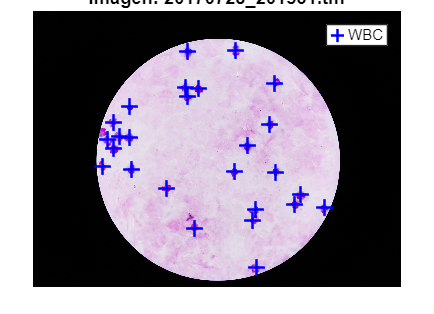

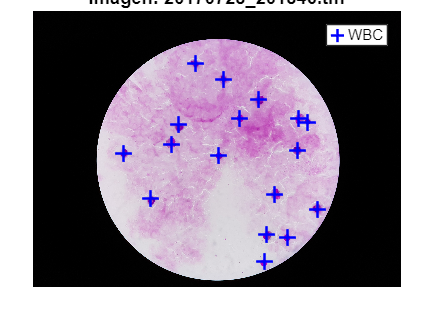

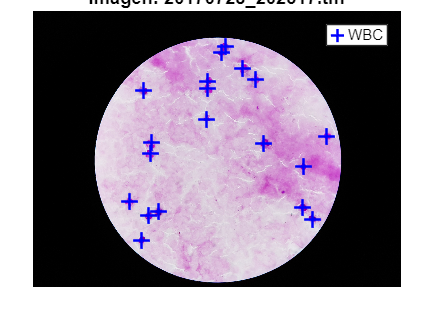

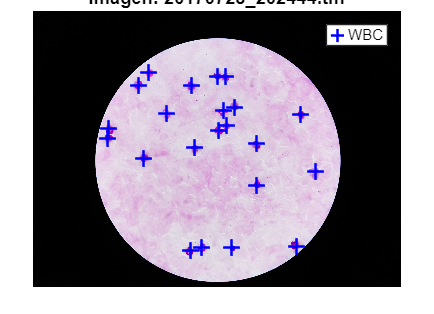

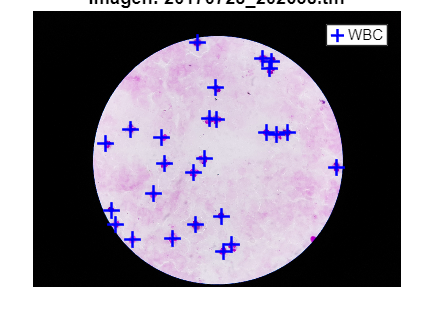

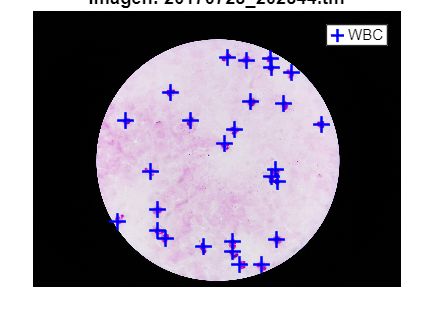

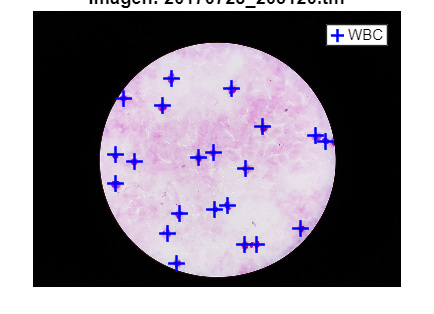

for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Annotations\TF201_HT6\results\2546', [imageFiles(i).name(1:end-5), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;
    plot(x_wbc, y_wbc, 'b+', 'MarkerSize', 10, 'LineWidth', 1.5);  % cruces azules

    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('WBC');
    hold off;
end

## **PARÁSITOS**

**No debería de haber**

### a) 3º K-means color

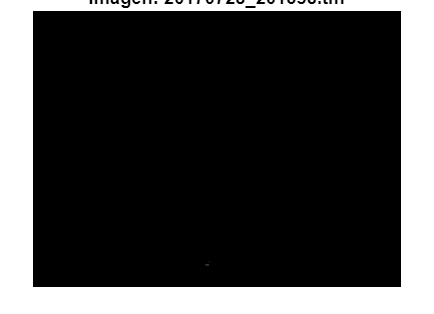

ruido = 2

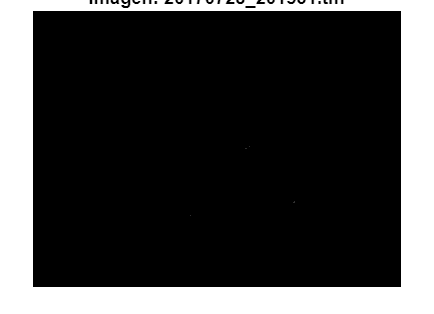

ruido = 7

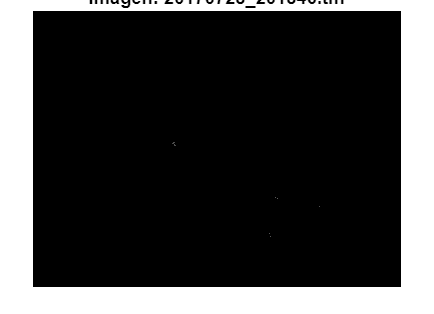

ruido = 13

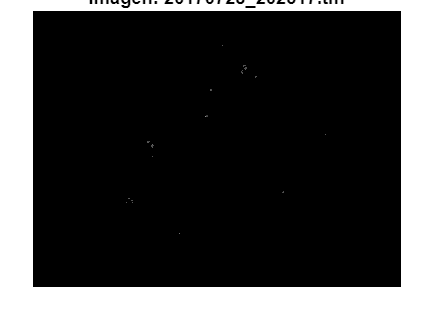

ruido = 21

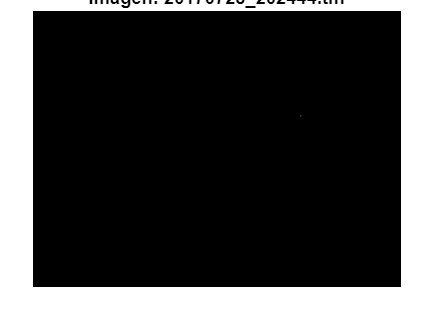

ruido = 2

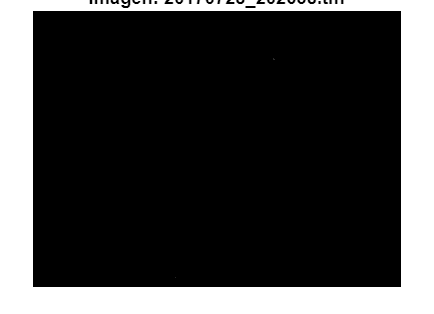

ruido = 7

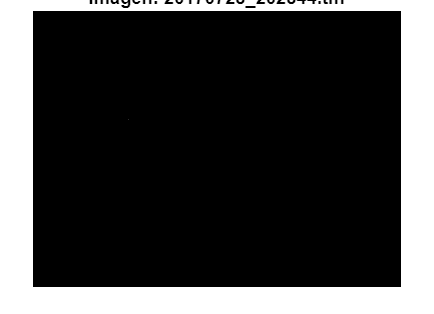

ruido = 5

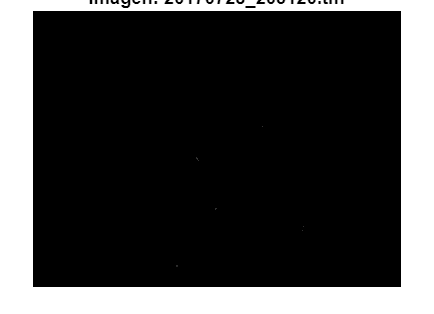

ruido = 9

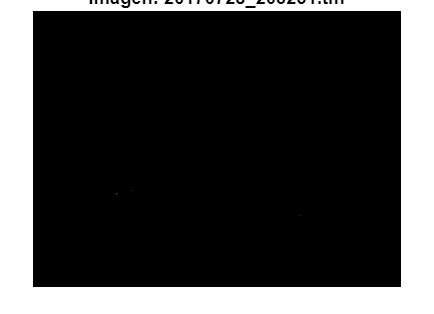

ruido = 7

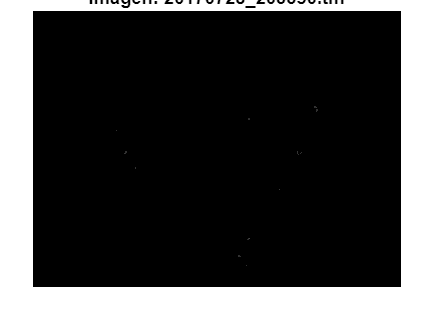

ruido = 22

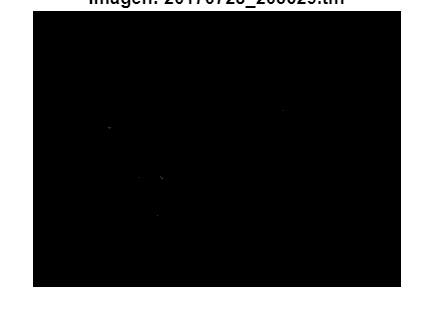

ruido = 5

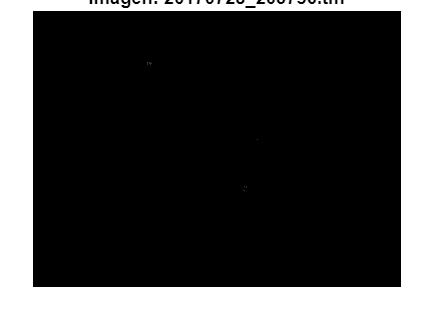

ruido = 6

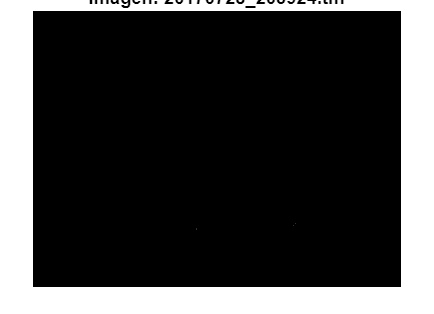

ruido = 5

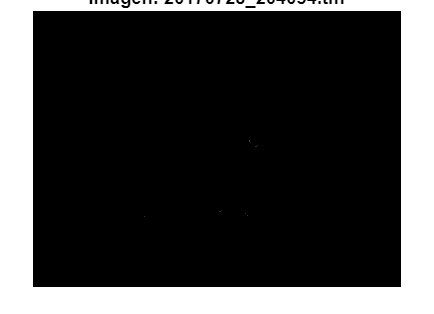

ruido = 16

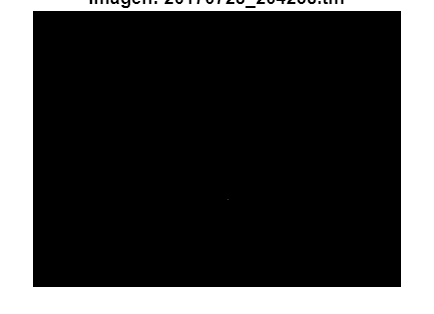

ruido = 1

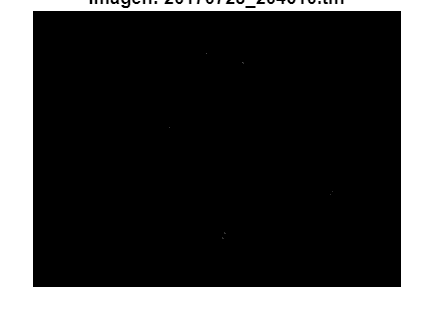

ruido = 13

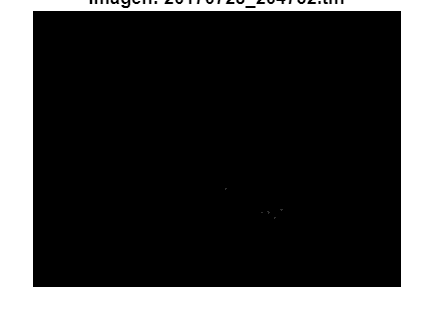

ruido = 7

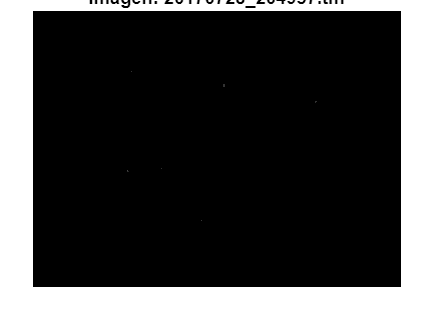

ruido = 10

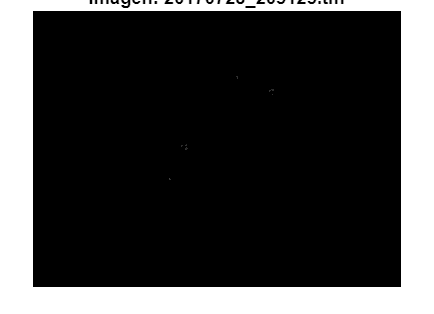

ruido = 12

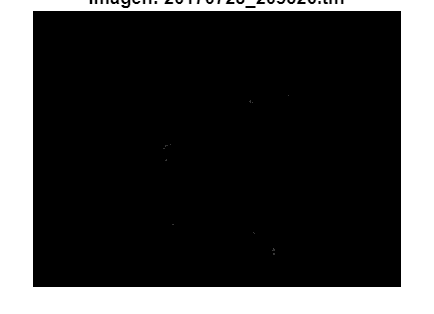

ruido = 16

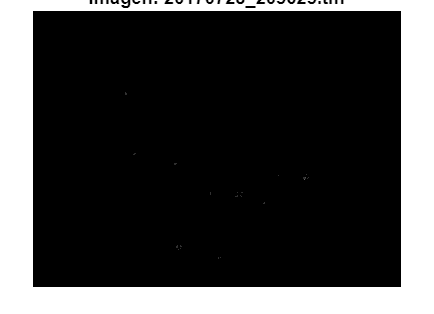

ruido = 25

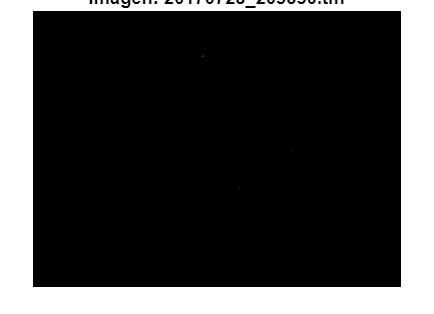

ruido = 4

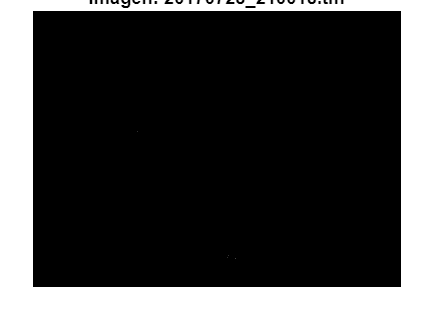

ruido = 4

total_ruido=0;
cantidad_imagenes_ruido=0;
for i = 1:length(imageFiles)
    % Fitxategiaren izen osoa
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    
    % Binario y escala de grises
    I_gray=rgb2gray(I);
    
    % Filtro
    I_sinruido=medfilt2(I_gray, [3 3]);
    
    % Aplicar imsegkmeans directamente (necesita uint8 o single)
    [L, cluster_centers] = imsegkmeans(I_sinruido, 3);

    mean_intensity = zeros(3,1);
    for c = 1:3
        mean_intensity(c) = mean(I_sinruido(L==c), 'all');
    end
    [~, idx_darkest] = min(mean_intensity);
    dark_points_mask = L == idx_darkest;
    
    % === Filtrar WBC (regiones grandes) ===
    WBC_mask = bwareaopen(dark_points_mask, 500);
    parasite_candidate_mask = dark_points_mask & ~WBC_mask;
    
    % === Procesamiento morfológico ===
    se = strel('disk', 2);
    dilated = imdilate(parasite_candidate_mask, se);
    filled = imfill(dilated, 'holes');
    opened = imopen(filled, strel('disk',1));
    
    % === Preparar imagen para imfindcircles ===
    mascara_parasitos = im2double(I_gray);
    mascara_parasitos(~opened) = 0;  % Fondo negro

    % Visualiza la máscara final
    figure;
    imshow(mascara_parasitos);
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    
    % Mirar las propiedades de los pixeles
    n=8; % neighbourhood

    % Contar puntos detectados
    CC = bwconncomp(mascara_parasitos,n);
    properties = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC,properties);
    ruido=size(caracteristicas,1)
    total_ruido=total_ruido+ruido;
    if ruido>=1
        cantidad_imagenes_ruido=cantidad_imagenes_ruido+1;
    end
end

total_ruido

total_ruido = 219

cantidad_imagenes=length(imageFiles)

cantidad_imagenes = 23

media=total_ruido/cantidad_imagenes

media = 9.5217